# Transfer Learning with MATLAB

In this exercise, you will use transfer learning to classify images into 1 of 5 different food categories:

- Pizza

- Hot Dog

- Ice Cream

- French Fries

- Chocolate Cake

You will also use this network to create a hotdog/not-hotdog classifier at the end.

The images used in this example come from the Food 101 dataset, which can be found at [https://www.vision.ee.ethz.ch/datasets_extra/food-101/](https://www.vision.ee.ethz.ch/datasets_extra/food-101/) 

## Accessing a pre-trained network

Load in alexnet and inspect the different layers

clear
addpath(genpath(pwd))

net = alexnet; 
layers = net.Layers;

## Create a datastore

We used a datastore previously to read images in a loop. With ImageDatastore you can also label images, set a custom read function and split images into different sets. 

Create a datastore, including subdirectories and add labels based on the filenames.

filePrefix = fullfile([filesep 'MATLAB Drive', filesep, 'Workshop', filesep, 'LargeFiles']);
filepath = [filePrefix,filesep,'04-Images'];

imds = imageDatastore(filepath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 

## Look at some random images

Let's get a feel for the dataset. Write some code that will let you inspect some of the images. You can get the label from the list of labels or from the second output of the datastore read functions.

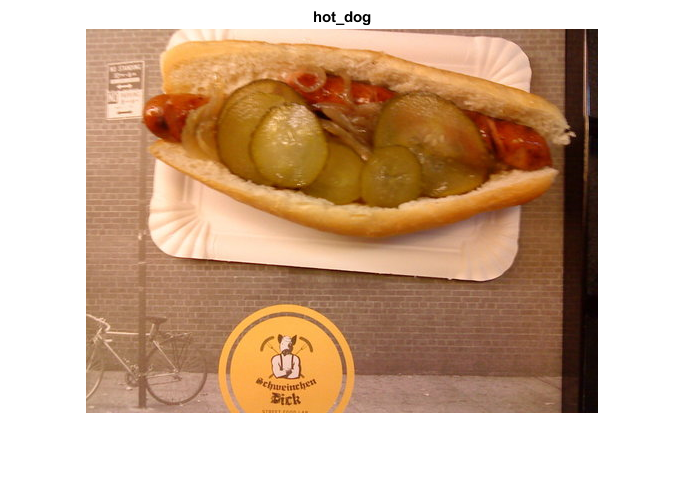

% Generate random number < # of total images
randNum = randi(length(imds.Files));
% Read random image from the datastore and visualize
[imTemp,info] = readimage(imds,randNum);

imshow(imTemp)
title(char(info.Label),'Interpreter','none')

## Splitting Image datastore into 3 sets:  | Train | Validate | Test |

It is a best practice to split our data into a training, validation and test set.

- Training - used to train our network by establishing proper weights that allow for accurate classification

- Validation - a dataset that you test the network on after training. If the results are poor, retrain the network with different hyperparameters and/or network architecture

- Test - an unseen dataset that is used as an unbiased measurement of network accuracy. Use this after you are happy with your validation performance.

There is not a perfect way to split your data, but people often do a 70/15/15 split. Use the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/datastore.spliteachlabel.html) function to split your datastore into the three desired sets.

[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

## Resize Images to Alexnet Input Requirement

There are many ways to perform this process. The fastest is to use an augmentedImageDatastore, which will resize our imagedatastore in mini-batches as we pass images through the network for training.  

sizeRequirement = net.Layers(1).InputSize;
inputSize = sizeRequirement(1:2);

DS = struct;

DS.auTrainDS = augmentedImageDatastore(inputSize,trainDS);
DS.auValDS = augmentedImageDatastore(inputSize,valDS);
DS.auTestDS = augmentedImageDatastore(inputSize,testDS);

## Modify the Network

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

Remember the 3 layers at the end of each network(the ones we talked about in MNIST)? Let's modify those to fit our needs.

- Fully Connected Layer - after all the convolution and max pooling layers, which detect features, this layer does the "high-level-reasoning" using its connection to all the activations in the previous layer.

- Softmax Layer - Computes the scores that a given image receives for each different category.

- Classification Layer - Determines the highest score and categorizes the image.

numClasses = numel(unique(imds.Labels));

layers(end-2) = fullyConnectedLayer(numClasses,'Name',['fc' num2str(numClasses)]);
layers(end) = classificationLayer('Name','classOut');

newLayers = layers;

## Set Training Options

Set the hyperparameters for this neural network.

initiallearnrate = 0.001;
valData         = DS.auValDS;
valDataPatience = 3;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',valData,...
    'Plots','training-progress',...
    'MiniBatchSize', 64,...
    'ValidationPatience', valDataPatience);


## Train and Validate the Network

Train the network with the training data and validate it with our validation data set (note: this is done automatically thanks to our training options). If the validation results are not adequate, tune hyperparameters and try again.

Initialization may take a minute before training begins


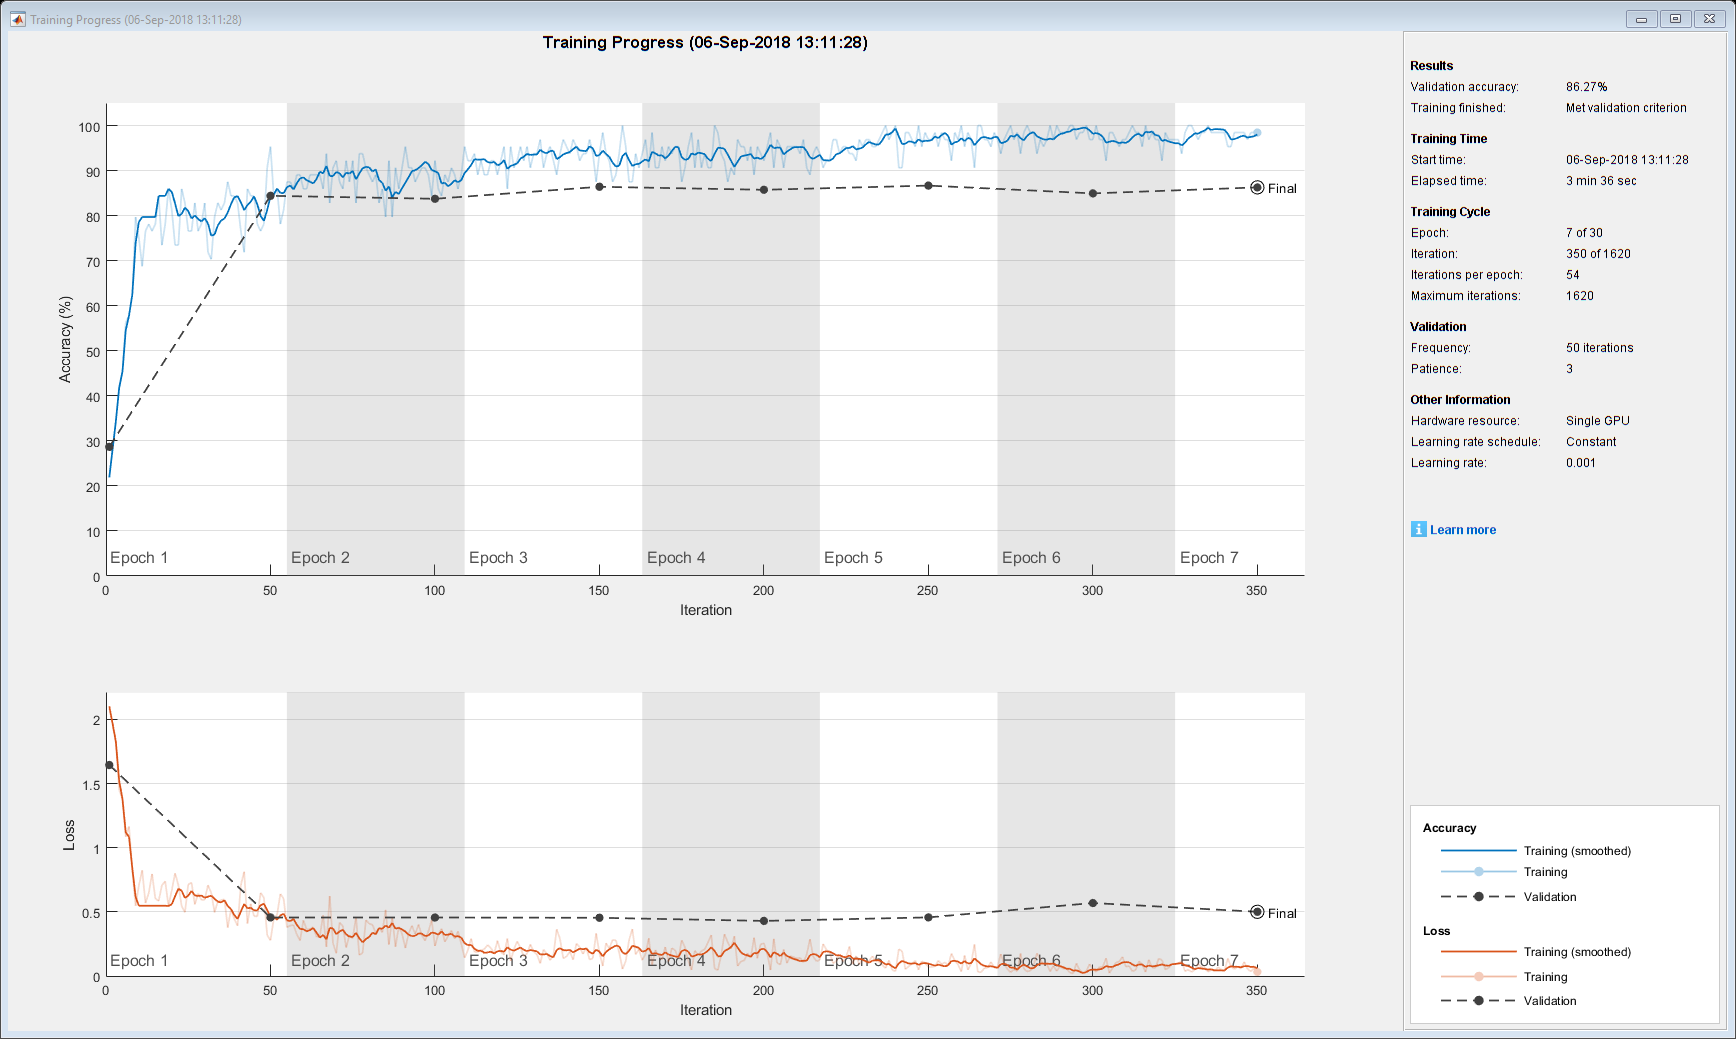

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:24 |       21.88% |       28.67% |       2.1017 |       1.6445 |          0.0010 |
|       1 |          50 |       00:00:53 |       95.31% |       84.40% |       0.2792 |       0.4572 |          0.0010 |
|       2 |         100 |       00:01:21 |       92.19% |       83.73% |       0.2344 |       0.4567 |          0.0010 |
|       3 |         150 |       00:01:48 |       93.75% |       86.40% |       0.1786 |       0.4546 |          0.0010 

doTraining = true;

if doTraining
    disp('Initialization may take a minute before training begins');
    net_SeeFood = trainNetwork(DS.auTrainDS, newLayers, trainOpts);
    % If you get out-of-memory error for GPU, go back to trainingOptions and reduce the 'MiniBatchSize'
else
    % load .mat file with trained network
    filepath = fullfile(filePrefix,'04-SeeFoodNetwork','net_SeeFood.mat');
    load(filepath)
end

## Test the Network

Once happy with validation results, test the network on the test dataset

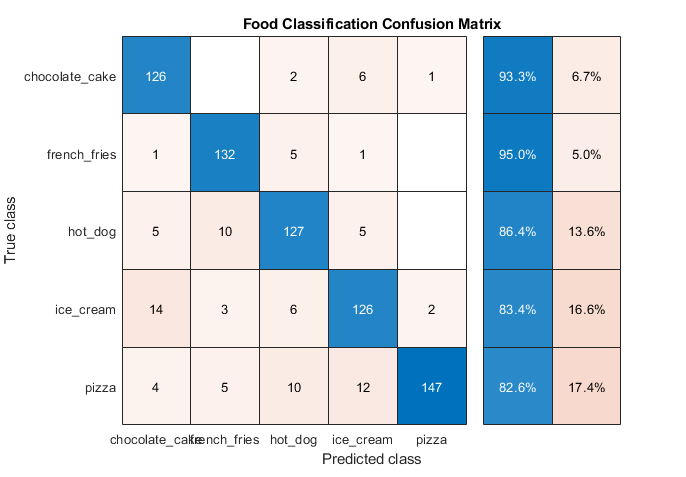

doTest = true;

if doTest
    [labels, scores] = classify(net_SeeFood, DS.auTestDS);
else
    load testResults.mat 
end

% Calculate accuracy
accuracy = sum(labels == testDS.Labels)/numel(labels)

% Confusion Matrix - visual inspection of accuracy and error
cm = confusionchart(labels, testDS.Labels);
cm.RowSummary = 'row-normalized';
cm.Title = 'Food Classification Confusion Matrix';


% Are there trends in the misclassifications?
% Where might these come from?

## View Some of the Results

Write a script that will let you view some of the images in the test dataset

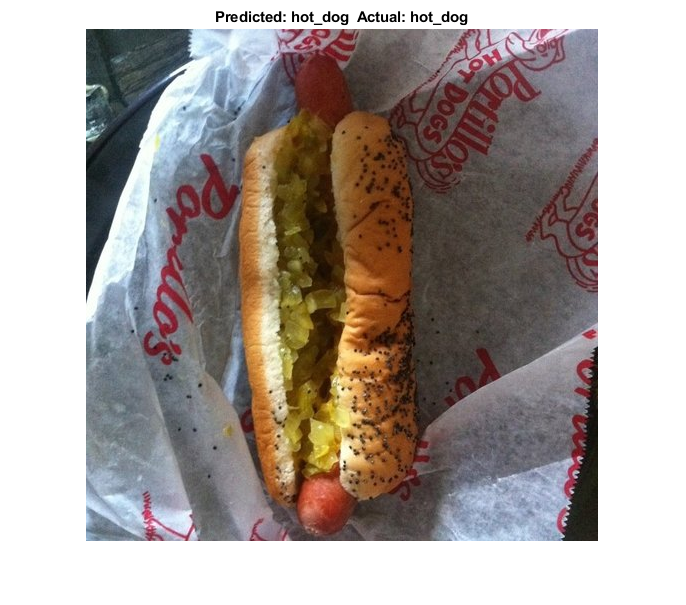

randNum = randi(length(testDS.Files));
imOriginal = readimage(testDS,randNum);
imResized = imresize(imOriginal, inputSize);

actualLabel = testDS.Labels(randNum);
predictedLabel = classify(net_SeeFood,imResized);
imshow(imOriginal)
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')

## Visualization

CNNs have traditionally been a black box. However, MATLAB lets you visualize weights in one of the network layers. We can see different convolution filters and activations. What do you notice?

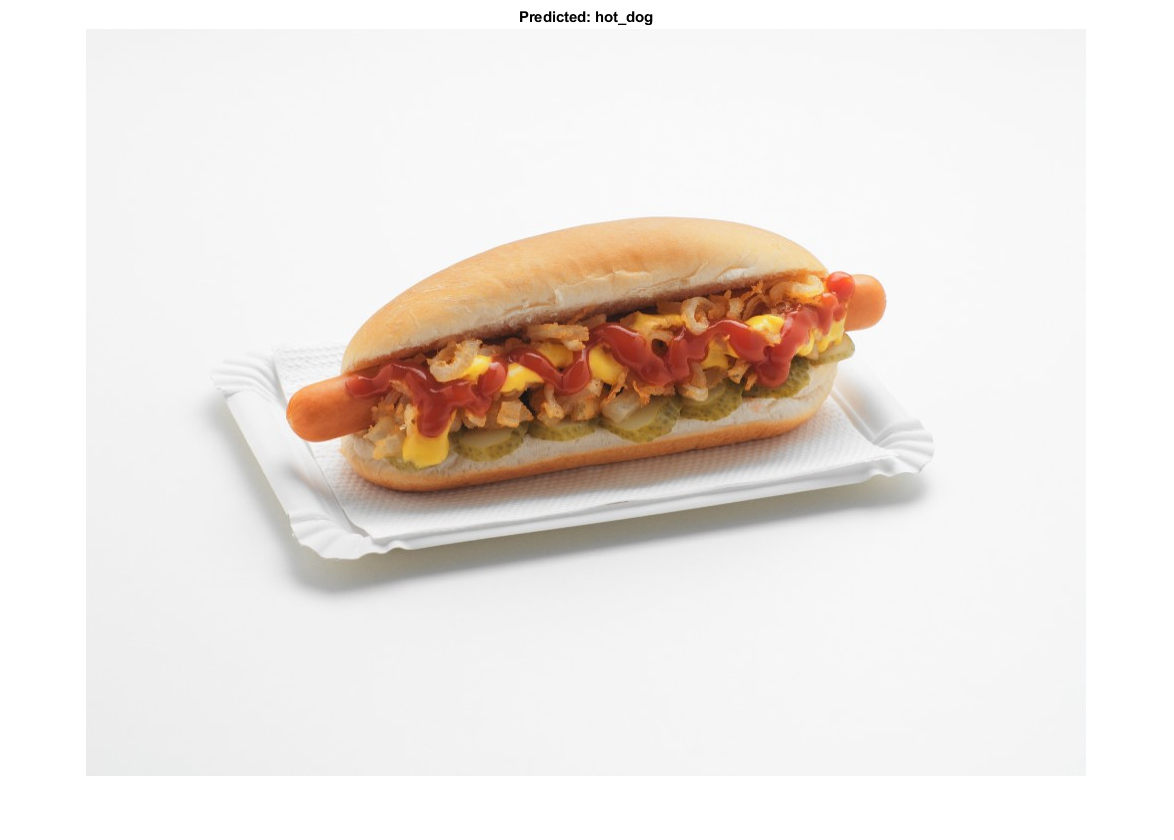

im = imread('hotdog.jpg');
imshow(im)
imR = imresize(im,inputSize);
label = classify(net_SeeFood,imR);
title(['Predicted: ' char(label) ],'Interpreter','none')

View the different weights of the filters used for convolution

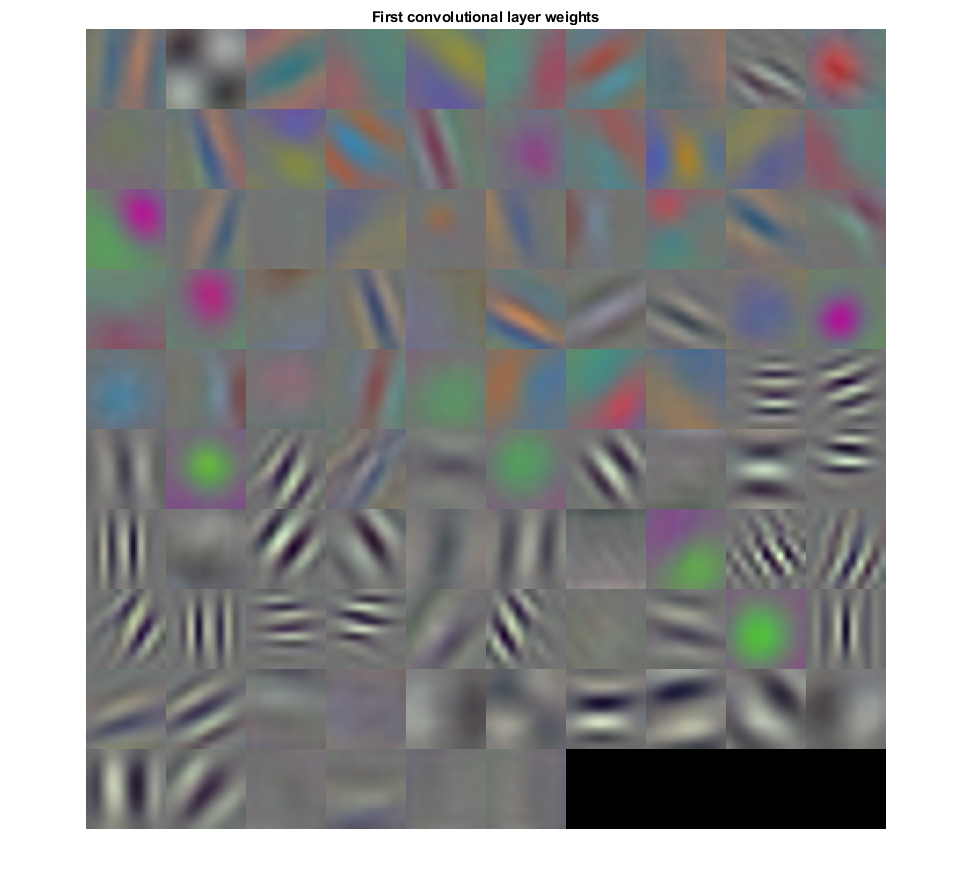

weights = net_SeeFood.Layers(2).Weights;
weights = mat2gray(weights);
montage(weights)
title('First convolutional layer weights')

View the activations in the first convolution layer

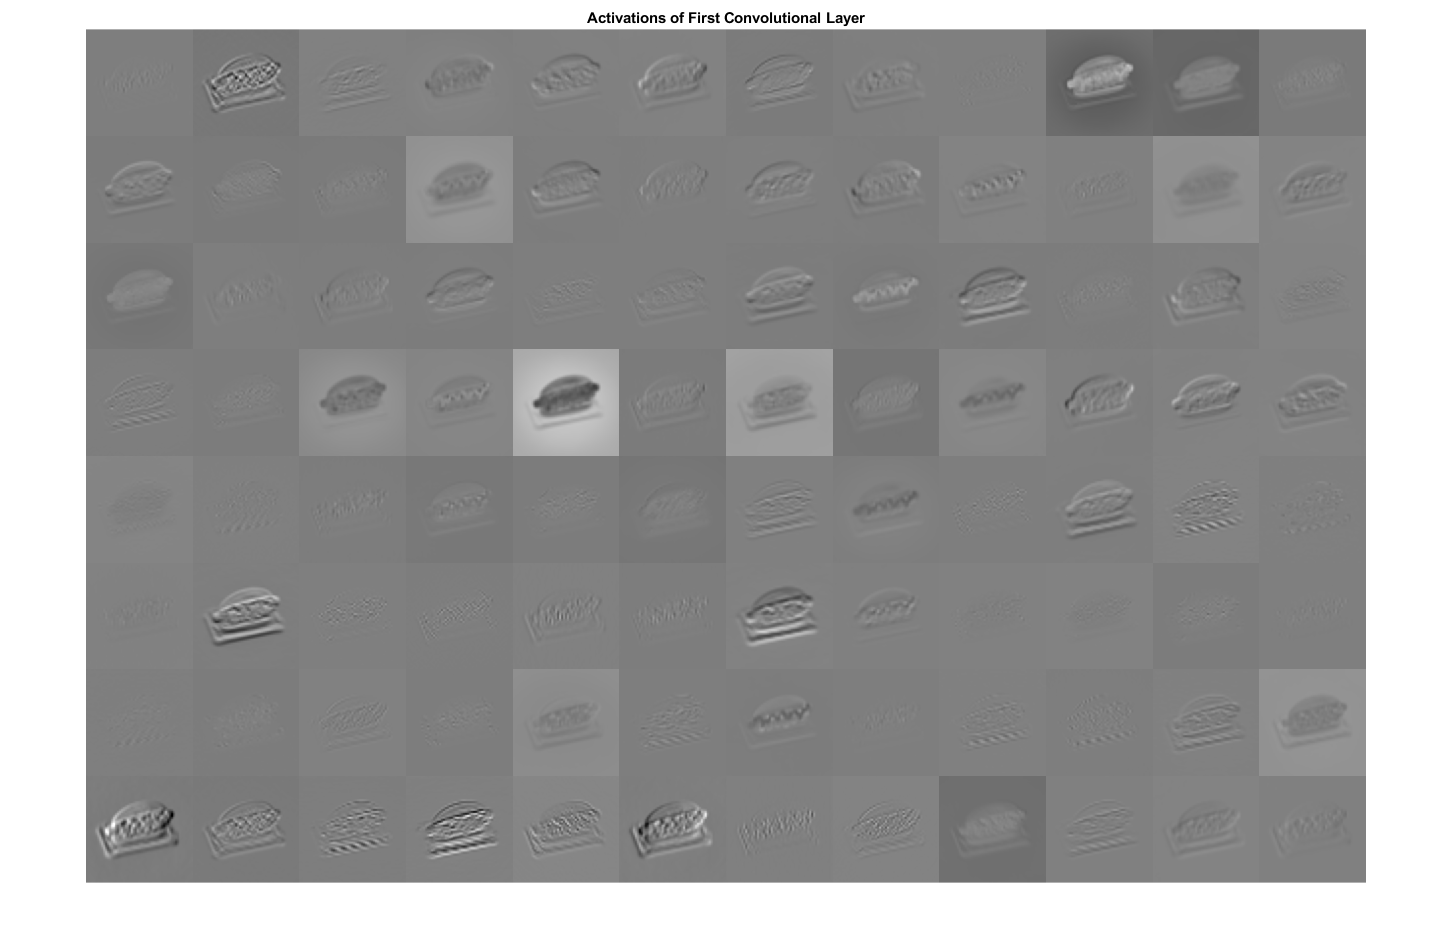

act1 = activations(net_SeeFood,imR,'conv1','OutputAs','channels');
sz = size(act1);
act1 = reshape(act1,[sz(1) sz(2) 1 sz(3)]);
figure;montage(mat2gray(act1),'Size',[8 12])
title('Activations of First Convolutional Layer')

## Try It with Random Internet Pictures

URL = '';
filename = '';
websave(filename, URL);

im = imread(filename);
im = imresize(im, inputSize);
classify(net_SeeFood, im)

## Build a Hotdog/Not-hotdog Classifier

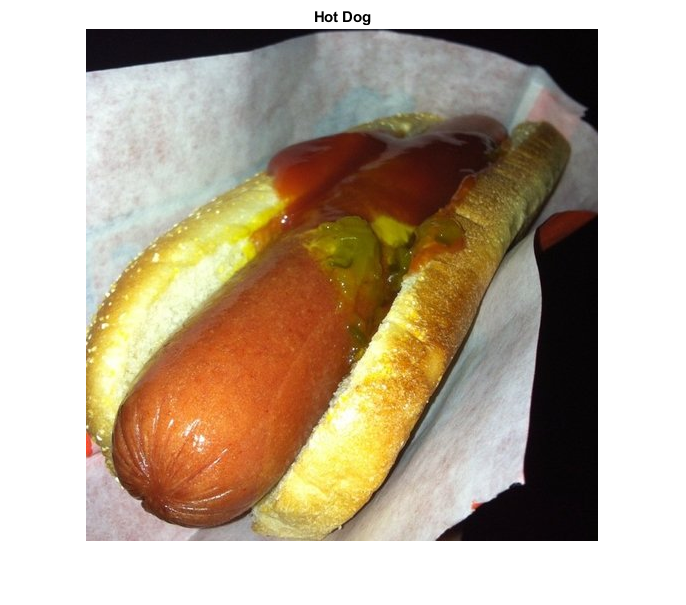

[a,fs] = audioread('Special Occasion.wav');
randNum = randi(length(testDS.Files));
imOriginal = imread(testDS.Files{randNum});
imResized = imresize(imOriginal, inputSize);
[imgLabel,score] = classify(net_SeeFood,imResized);

imshow(imOriginal)

if imgLabel == 'hot_dog' && max(score) > 0.85
    title('Hot Dog')
    sound(a,fs) 
else
    title('Not Hot Dog')
end

*Copyright 2019 The MathWorks, Inc.*